# **TALLER SEGUNDO CORTE**

- Laura Camila Machado Prada

- Nestor Javier Mahecha Parra

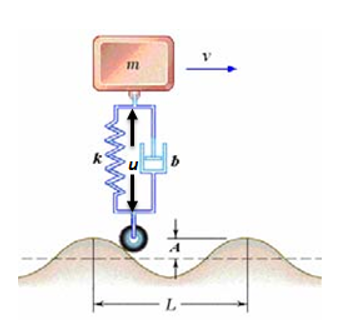

**MODELO**

- -$M\ddot{y}=K(y+P)+B(\dot y+\dot P)-u(t
)$

**ECUACIONES**

- 
$$Z_2=\dot {Z_1}$$


- -$M\dot{Z_2}=K(Z_1+P)+B(Z_2+\dot P)-u(t
)$

**ECUACIÓN EN MATRICES DE ESTADO **

clc
clear all
syms K M b s
A1=[0    1;
   -K/M -b/M]

$$A1 = \left(\begin{array}{cc} 0 & 1\\ -\frac{K}{M} & -\frac{b}{M} \end{array}\right)$$

B1=[0; 1/M]

$$B1 = \left(\begin{array}{c} 0\\ \frac{1}{M} \end{array}\right)$$

C1=[1 0]                     %Controlar posición

C1 =      1     0


D1=0

D1 = 0

E1=[0; -K/M]

$$E1 = \left(\begin{array}{c} 0\\ -\frac{K}{M} \end{array}\right)$$

F1=[0; -b/M]

$$F1 = \left(\begin{array}{c} 0\\ -\frac{b}{M} \end{array}\right)$$

funcion=(C1*(s*eye(2)-A1)^(-1))*B1

$$funcion = \frac{1}{M\,s^{2}+b\,s+K}$$


%ecuacion=

syms s
b=10;
K=20;
M=3;
A=[0    1;
   -K/M -b/M]

A =          0    1.0000
   -6.6667   -3.3333


B=[0; 1/M]

B =          0
    0.3333


C=[1 0]                     %Controlar posición

C =      1     0


D=0

D = 0

E=[0; -K/M]

E =          0
   -6.6667


F=[0; -b/M]

F =          0
   -3.3333


[num,den]=ss2tf(A,B,C,D)

num =          0         0    0.3333


den =     1.0000    3.3333    6.6667


sys=tf(num,den)

sys =
 
         0.3333
  ---------------------
  s^2 + 3.333 s + 6.667
 
Continuous-time transfer function.



%El tiempo de la perturbación es 8s, por tener una frecuencia de pi/4 rad/s

- *SIMULACIÓN DE LA PLANTA EN LAZO ABIERTO*

*Esquema de simulación*

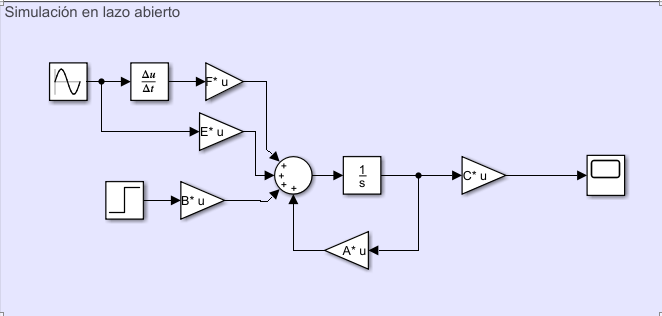

Características de la perturbación

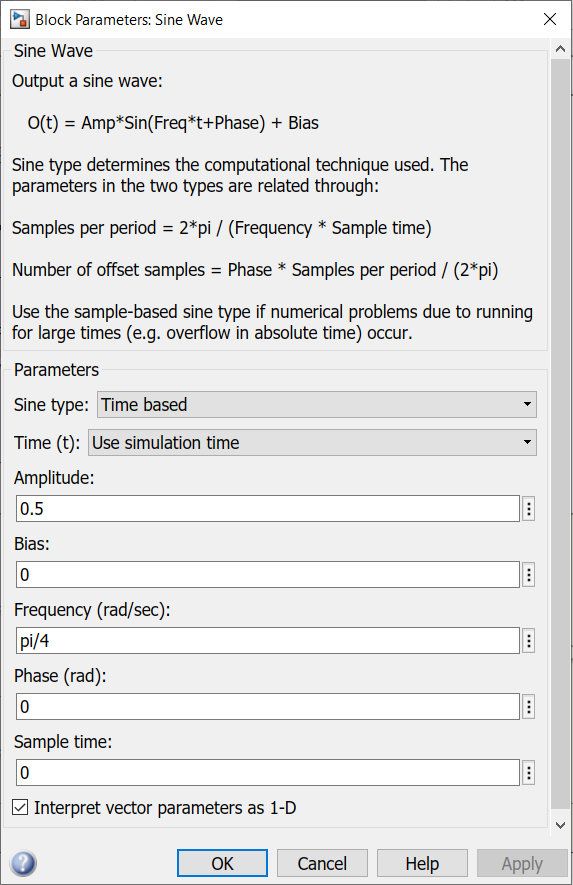

*Respuesta en lazo abierto *

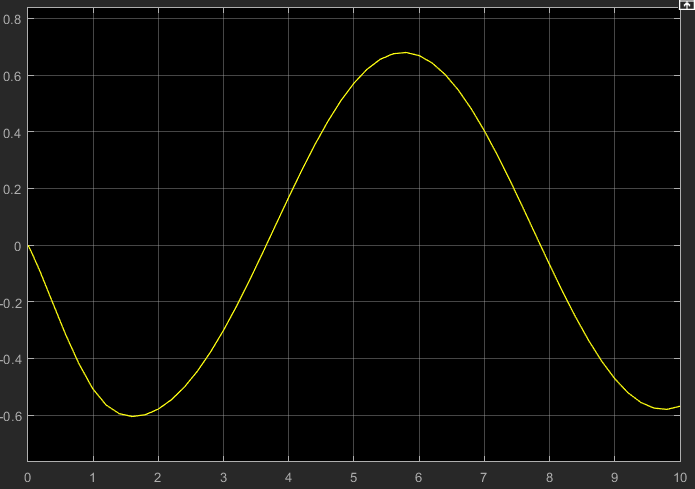

- *PID CONTINUO*

syms x kd kp ki z
numc=kd*s^2+kp*s+ki;
denc=s;
%Separar denominador y numerador de la funcion de transferencia y dejarlo
%con s
[numdis,dendis]=tfdata(sys,'v')

numdis =          0         0    0.3333


dendis =     1.0000    3.3333    6.6667


NumeradorR=poly2sym(numdis,s)

$$NumeradorR = \frac{1}{3}$$

DenominadorR=poly2sym(dendis,s)

$$DenominadorR = s^{2}+\frac{10\,s}{3}+\frac{20}{3}$$

%hallar denominador del polinomio caracteristico
pc=collect(NumeradorR*numc+DenominadorR*denc)

$$pc = s^{3}+\left(\frac{\mathrm{kd}}{3}+\frac{10}{3}\right)\,s^{2}+\left(\frac{\mathrm{kp}}{3}+\frac{20}{3}\right)\,s+\frac{\mathrm{ki}}{3}$$

%hallar polinomio deseado
zd=0.7;
tsd=1;
wnd=4.6/(zd*tsd)

wnd = 6.5714

%Manejando simbolicos polinomio
pd=expand((s^2+2*wnd*zd*s+wnd^2)*(s+5*wnd*zd))

$$pd = s^{3}+\frac{161\,s^{2}}{5}+\frac{62422\,s}{245}+\frac{48668}{49}$$

Pccoef=coeffs(pc,s)

$$Pccoef = \left(\begin{array}{cccc} \frac{\mathrm{ki}}{3} & \frac{\mathrm{kp}}{3}+\frac{20}{3} & \frac{\mathrm{kd}}{3}+\frac{10}{3} & 1 \end{array}\right)$$

Pdcoef=coeffs(pd,s)

$$Pdcoef = \left(\begin{array}{cccc} \frac{48668}{49} & \frac{62422}{245} & \frac{161}{5} & 1 \end{array}\right)$$

Sol=double(vpa(struct2array(solve(Pdcoef==Pccoef,[ki kp kd])),2))

Sol = 	1.0e+03 *

    2.9797    0.7444    0.0866


Ki=Sol(1)

Ki = 2.9797e+03

Kp=Sol(2)

Kp = 744.3510

Kd=Sol(3)

Kd = 86.6000

*Esquema de simulación*

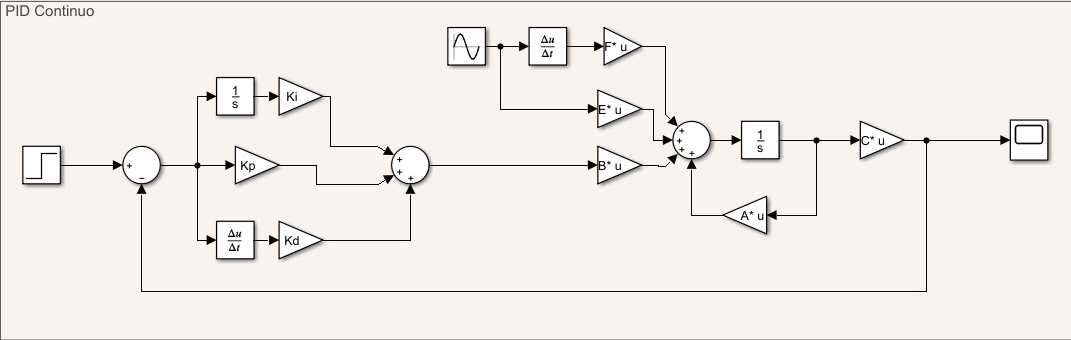

*Respuesta sin perturbaciones*

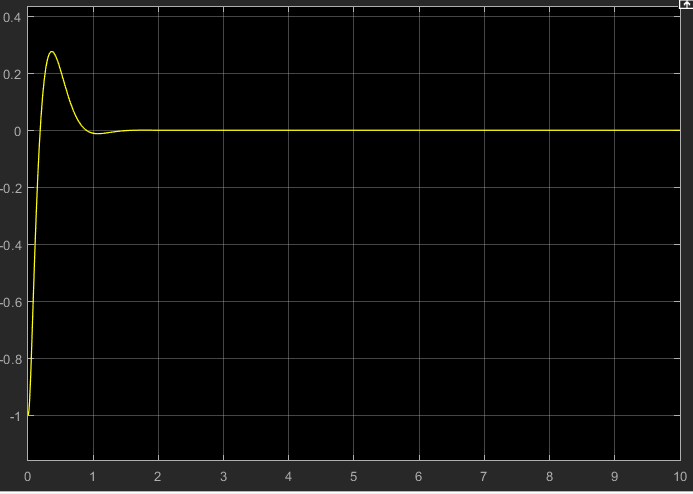

*Respuesta con perturbaciones*

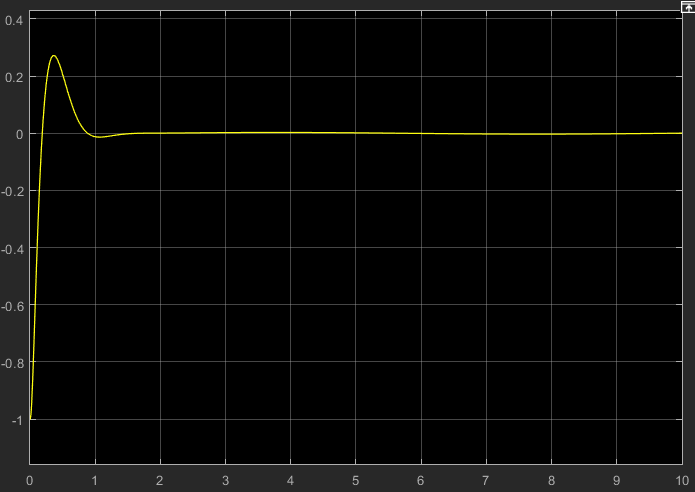

**Ecuación en diferencias PID Continuo**


$$u(k)=86.6*e(k)+744.351*e(k-1)+2.9797*10^3*e(k-2)$$


*PID CONTINUO DISCRETO*

%continuo a discreto
numcd=[Kd Kp Ki]

numcd = 	1.0e+03 *

    0.0866    0.7444    2.9797


dencd=[1 0]

dencd =      1     0


ts=tsd/30;
td=Kd/Kp

td = 0.1163

ti=Kp/Ki

ti = 0.2498

q0=Kp*(1+(ts/(2*ti))+(td/ts))

q0 = 3.3920e+03

q1=Kp*((ts/(2*ti))-1-((2*td)/ts))

q1 = -5.8907e+03

q2=Kp*(td/ts)

q2 = 2.5980e+03

N1=[q0 q1  q2]

N1 = 	1.0e+03 *

    3.3920   -5.8907    2.5980


D1=[1 -1]

D1 =      1    -1


*Esquema de simulación   *

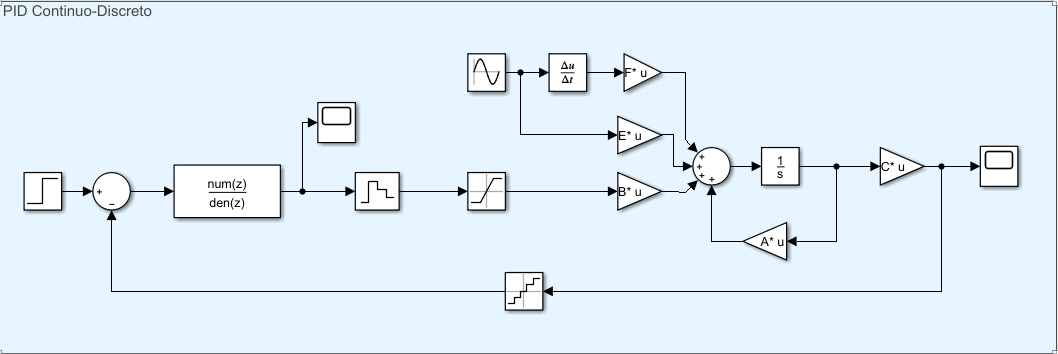

*Respuesta sin perturbaciones*

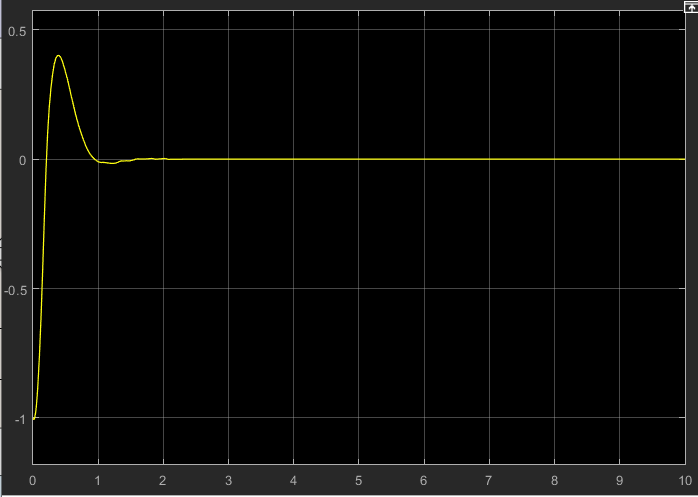

*Respuesta con perturbaciones*

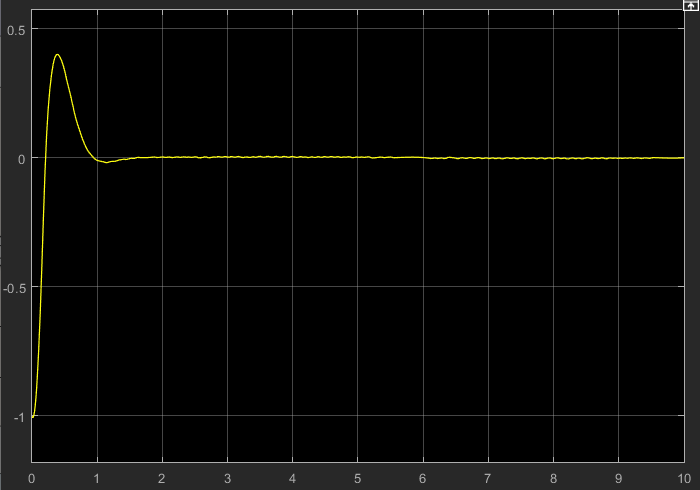

**Ecuación en diferencias PID Continuo- Discreto**


$$u(k)=4.2456*10^3*e(k)-7.6351*10^3*e(k-1)+3.4640*10^3*e(k-2)+u(k-1)$$


*PID DISCRETO DISCRETO *

zd=0.7;
tsd=1;
tm=tsd/10;
wnd=4.6/(zd*tsd)

wnd = 6.5714

syms q0 q1 q2 s0 z            
funciond=c2d(sys,tm,'zoh')

funciond =
 
  0.001488 z + 0.001331
  ---------------------
  z^2 - 1.66 z + 0.7165
 
Sample time: 0.1 seconds
Discrete-time transfer function.



numd=[q0 q1 q2];
dend=[1 s0-1 -s0 ];%(z-1)*(z+S0)
pcnum=poly2sym(numd,z);
pcden=poly2sym(dend,z);
[numdpd,dendpd]=tfdata(funciond,'v');
numpd=vpa((poly2sym(numdpd,z)),4);
denpd=vpa((poly2sym(dendpd,z)),4);
planta=numpd/denpd;
controlador=pcnum/pcden

$$controlador = \frac{q_{0}\,z^{2}+q_{1}\,z+q_{2}}{z^{2}+\left(s_{0}-1\right)\,z-s_{0}}$$

controladorplanta=(simplify((planta*controlador)/(1+(planta*controlador))));
[u,j]=numden(controladorplanta);
u1=coeffs(j,z,'All');
u2=vpa(u1/u1(1),2)

$$u2 = \left(\begin{array}{ccccc} 1.0 & 1.5e-3\,q_{0}+1.0\,s_{0}-2.7 & 1.3e-3\,q_{0}+1.5e-3\,q_{1}-2.7\,s_{0}+2.4 & 1.3e-3\,q_{1}+1.5e-3\,q_{2}+2.4\,s_{0}-0.72 & 1.3e-3\,q_{2}-0.72\,s_{0} \end{array}\right)$$

%%Polinomio deseado
PD_Cont = [1 (2*zd*wnd) wnd^2]        %polinomio deseado en continuo        

PD_Cont =     1.0000    9.2000   43.1837


FT_PD = tf(1,PD_Cont);
FT_PD_D = c2d(FT_PD, tm, 'zoh')

FT_PD_D =
 
  0.003638 z + 0.002671
  ----------------------
  z^2 - 1.126 z + 0.3985
 
Sample time: 0.1 seconds
Discrete-time transfer function.



PD_Disc = FT_PD_D.den{1};
PD_PID = conv(PD_Disc, conv([1 -0.1], [1 -0.1]))

PD_PID =     1.0000   -1.3261    0.6337   -0.0910    0.0040


%Solución
sold=struct2array((solve(u2==PD_PID,[q0 q1 q2 s0])))

$$sold = \left(\begin{array}{cccc} 553.26375039871098761467412100102 & -752.98573340697463034477864325949 & 278.00675842125107370720800634144 & 0.51091720200816783231551064774053 \end{array}\right)$$

Q0=double(sold(1))

Q0 = 553.2638

Q1=double(sold(2))

Q1 = -752.9857

Q2=double(sold(3))

Q2 = 278.0068

S0=double(sold(4))

S0 = 0.5109

Esquema de simulación

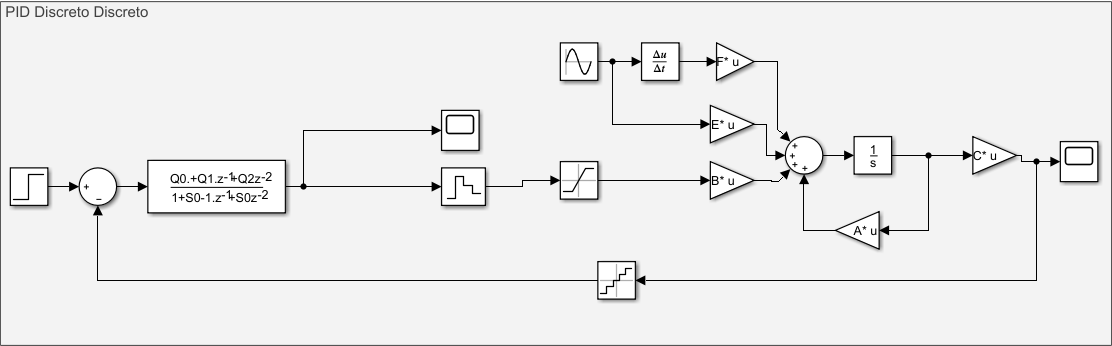

Respuesta sin oscilaciones

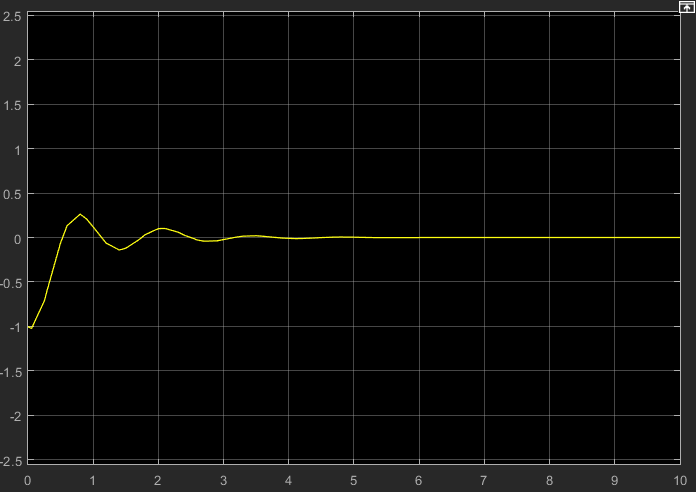

Respuesta con oscilaciones

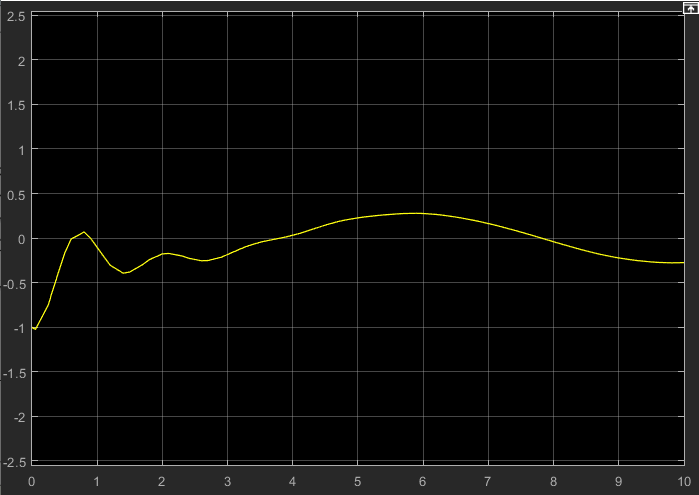

**Ecuacion en diferencias discreto discreto**


$$u(k)=36.222*e(k)-39.1747*e(k-1)+15.179*e(k-2)+0.7007*u(k-1)-0.2993*u(k-2)$$


*CONTROLADOR POR LGR*

% syms z 
% tsd=3;
% zd=0.7;
% sysd=c2d(sys,0.3,'zoh') %Por el tiempo de establecimiento en 3 
% sysd2=zpk(sysd)
% [cero,polo,gananciaplanta]=zpkdata(sysd)
% ceros=cell2mat(cero)
% polos=cell2mat(polo)
% T=tsd/10;
% wn=4/(tsd*zd)
% ws=2*pi/T
% wd=wn*sqrt(1-(zd)^2)
% %Punto de prueba
% ppm=exp(-T*zd*wn);
% ppf=T*wd;
% zp= complex(ppm*cos(ppf),ppm*sin(ppf))
% %Encontrar ángulos
% %Cero
% %Como dan ángulos conjugados entonces
% v1=[zp]-[ceros];
% angulo1=angle(v1)*180/pi
% %Polo 1
% v2=[zp]-real(polos(1))-imag(polos(1))*j
% angulo2=angle(v2)*180/pi
% %Polo 2
% v3=[zp]-real(polos(2))+imag(polos(2))*j
% angulo3=angle(v3)*180/pi
% %Polo en 1 dado por el integrador 
% v4=zp-1;
% angulo4=angle(v4)*180/pi
% %Ángulo a compensar
% compensar=abs(angulo1-angulo2-angulo3-angulo4+180)
% %Ángulo B
% anguloB=(angulo1-angulo4+180)
% %Encontrar B
% B=-imag(zp)/tand(anguloB)+real(zp)
% %Encontrar K
% ganancia=real(1/abs(((gananciaplanta*(zp-ceros)/((zp-B)*(zp-1))))))
% %Compensador
% numerador=conv([1 -polos(1)],[1 -polos(2)])
% denominador=([1 -(B+1) B])
% %K*(z-polos(1))*(z(polos(2)))/(z-B)
% 

*Esquemas de simulación*

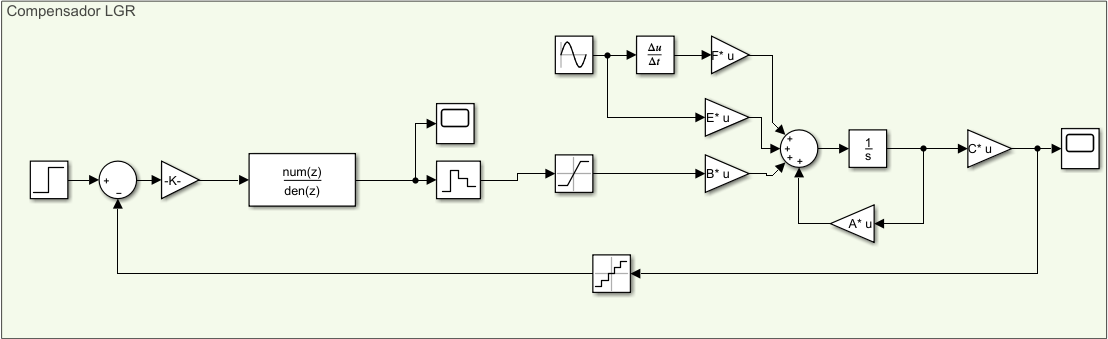

*Respuesta sin oscilaciones*

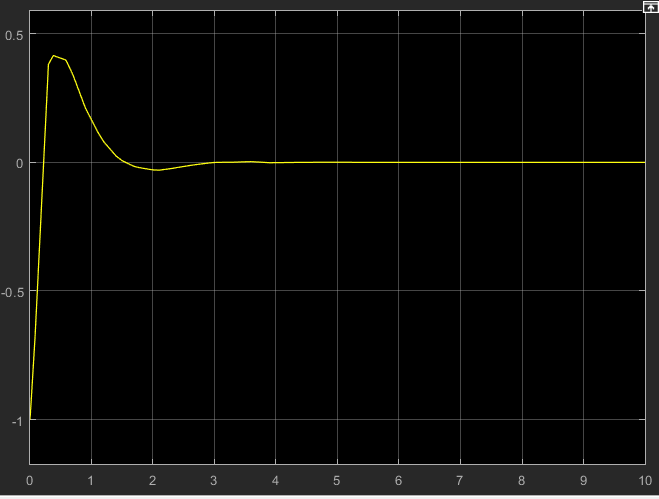

*Respuesta con oscilaciones*

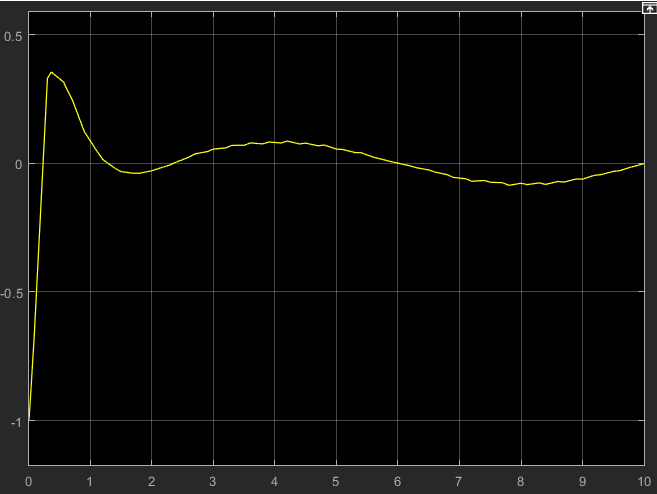

**Ecuaciones en diferencia LGR**

 
$$u(k)=12.12*e(k)-12.2*e(k-1)+4.459*e(k-2)+1.3582*u(k-1)-0.3582*u(k-2)$$


COMPENSADOR POR ANULACIÓN DE PLANTA

% %El periodo de muestreo es tsd/10 y T=tsd/5
% %M retroalimentado en Z
% tsd=0.7;
% tm=tsd/10;
% nummrz=[1-exp(-1/2)];
% denmrz=[1 -1]
% %Planta discretizada
% sysd=c2d(sys,tm,'zoh')
% sysd2=zpk(sysd)
% [Zi,Pi,Ki]=zpkdata(sysd);
% %Estos van con signo contrario al igualarlos a cero
% ceroanu=cell2mat(Zi)
% Pi=cell2mat(Pi)
% numanu=conv([ 1 -Pi(1)],[1 -Pi(2)])
% denanu=conv([1 -ceroanu],[1 -1])
% %hallar K
% gananciaanu=nummrz/Ki
% %Ecuacion en diferencias
% %uk=K(ek-Pi(2)*ek-1)-(-Zi)*uk-1

Esquema de simulación

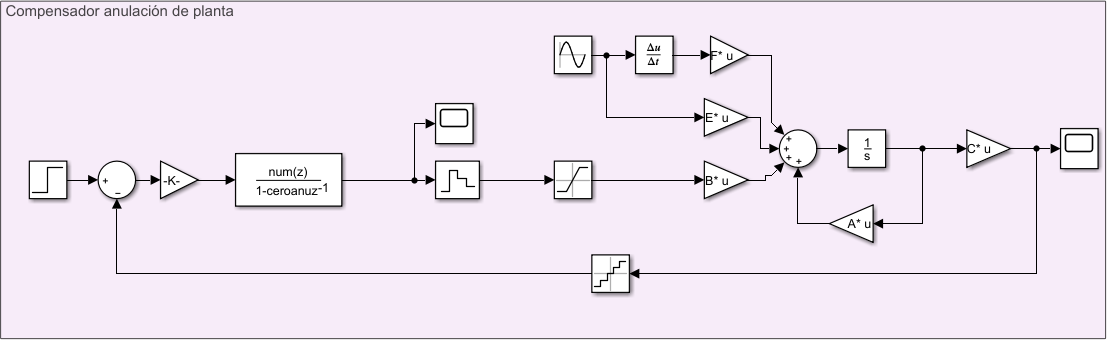

Respuesta sin perturbación

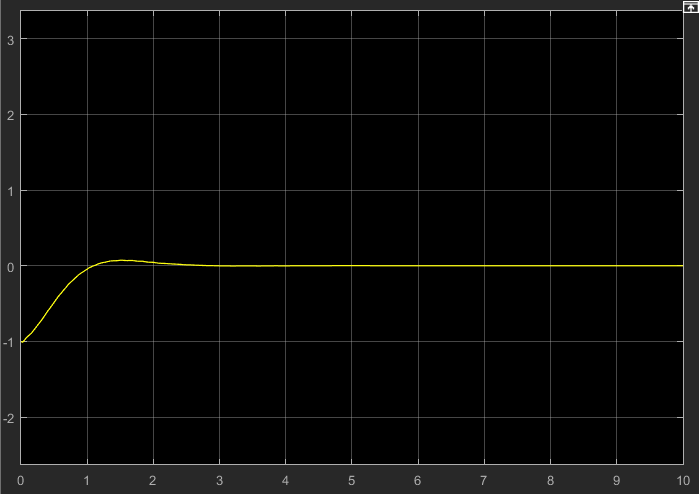

Respuesta con pertrubación

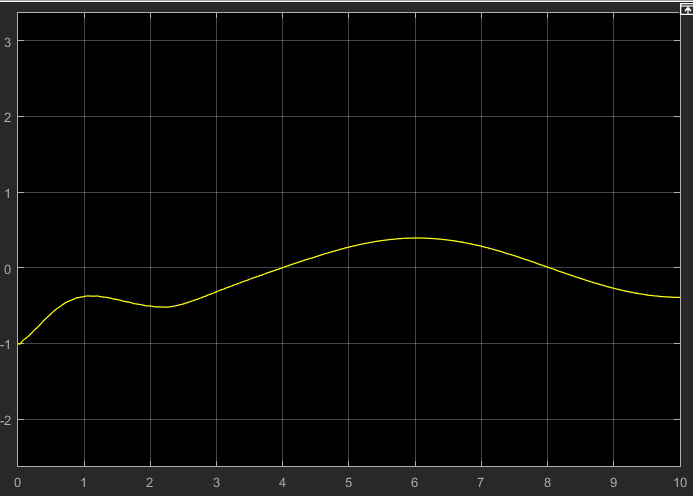

**Ecuación en diferencias anulación de planta**


$$u(k)=403.8*e(k)-698*e(k-1)+309.3*e(k-2)+0.0851*u(k-1)+0.9149*u(k-2)$$


*COMPENSADOR POR ANULACIÓN DE PLANTA RESPUESTA MÍNIMA*

% %El periodo de muestreo es tsd/10 y T=tsd/5
% %M retroalimentado en Z
% tsd=0.7;
% tm=tsd/10;
% %Planta discretizada
% sysd=c2d(sys,tm,'zoh')
% sysd2=zpk(sysd)
% [Zi2,Pi2,Ki2]=zpkdata(sysd);
% %Estos van con signo contrario al igualarlos a cero
% cerores=cell2mat(Zi2)
% Pi2=cell2mat(Pi2)
% numres=conv([ 1 -Pi2(1)],[1 -Pi2(2)])
% denres=conv([1 -cerores],[1 -1])
% %hallar K
% gananciares=1/Ki2
% %Ecuacion en diferencias
% %uk=K(ek-Pi(2)*ek-1)-(-Zi)*uk-1

Esquema de simulación

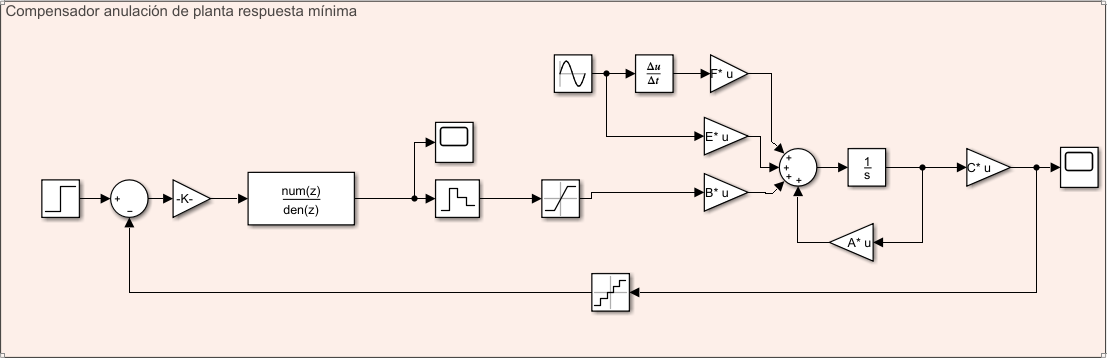

Respuesta del sistema sin oscilaciones:

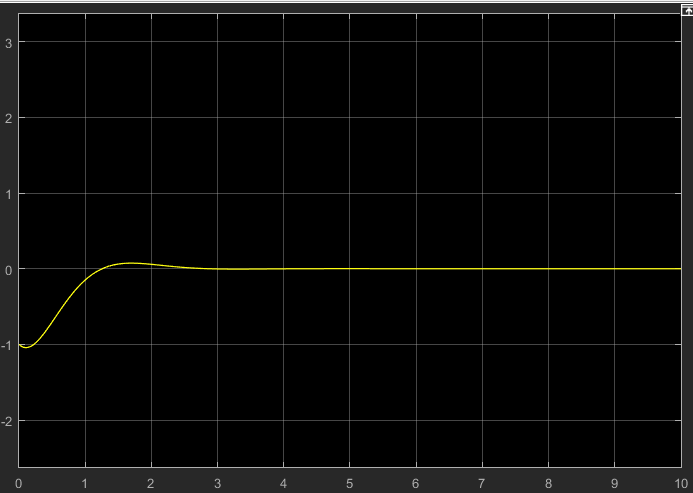

Respuesta del sistema con oscilaciones

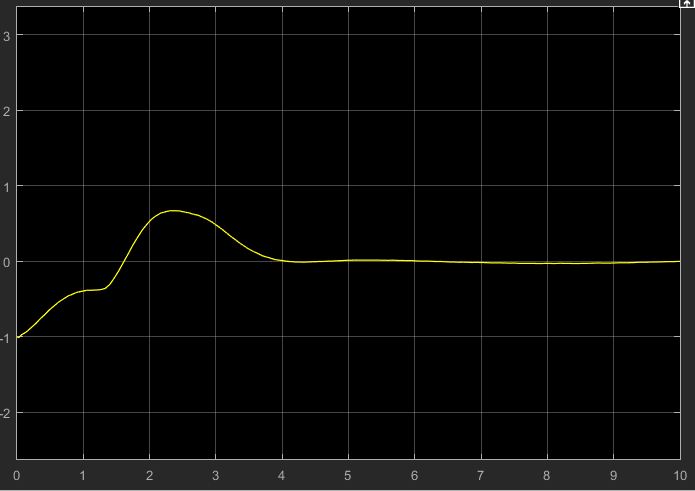

**Ecuación en diferencias Tiempo de respuesta mínimo**


$$u(k)=1.325*10^3*e(k)-2.335*10^3*e(k-1)+1.049*10^3*e(k-2)-0.9912*u(k-1)$$


*COMPENSADOR POR OSCILACIONES MUERTAS*

% syms z m1 a1
% tiempo=0.5/10
% sysd=c2d(sys,tiempo,'zoh')
% sysd2=zpk(sysd)
% [cero polo ganancia]=zpkdata(sysd);
% ceros=cell2mat(cero)
% polos=cell2mat(polo)
% mz=collect(expand((1-ceros*z)*(m1*z)))
% c1=coeffs(mz,z)
% mz2=-collect(expand((1-z)*(1+a1*z)-1))
% c2=coeffs(mz2,z)
% [A1 M1]=solve(c1==c2,[a1 m1]);
% vpa(A1,4)
% vpa(M1,4)
% Mzr=(1-ceros*z^-1)*M1*z^-1
% 
% ncont=double(conv([1 -polos(2)],[1 -polos(1)]))%Numerador
% %ncr=coeffs(ncont,z);
% dcont=conv([1 -1],[1 double(A1)])%Denominador 
% kih=double(M1/ganancia) %Ganancia 

*Esquema de simulación*

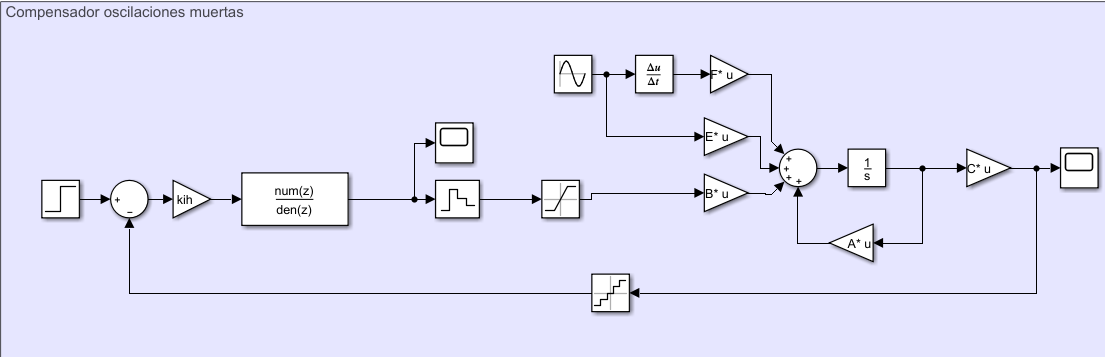

*Respuesta sin perturbación*

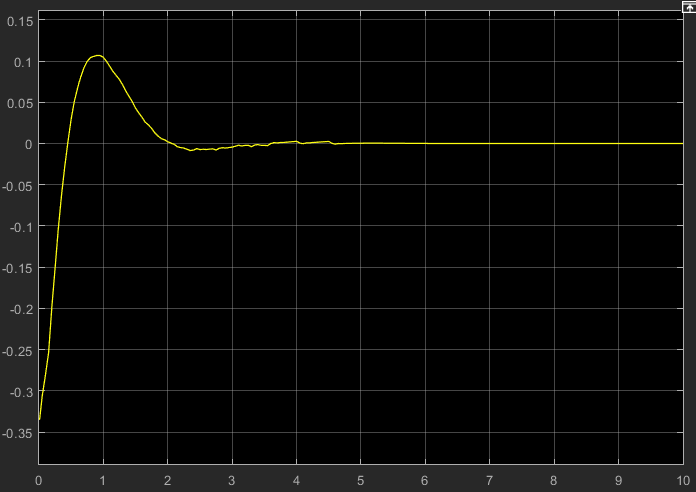

*Respuesta con perturbación*

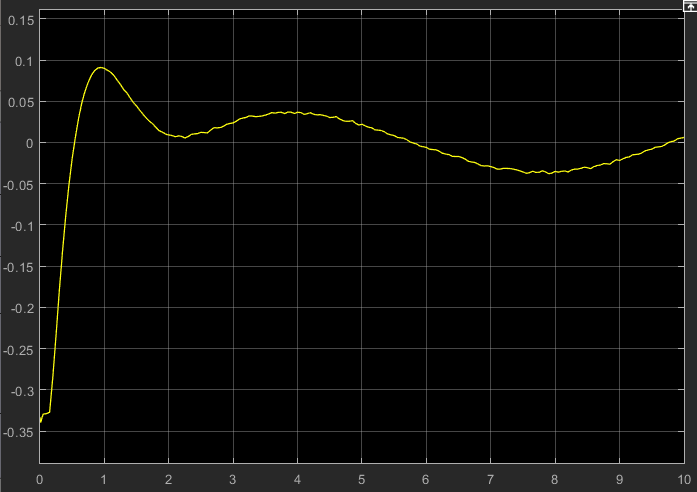

**Ecuacion en diferencias Oscilaciones Muertas**


$$u(k)=1.3046*10^3*e(k)-2.3889*10^3*e(k-1)+1.1043*10^3*e(k-2)+0.5139*u(k-1)+0.4861*u(k-2)$$


*COMPENSADOR POR FRECUENCIA*

% ts=0.08;
% T=ts/40;
% syms z W
% sysd=c2d(sys,T,'zoh')
% 
% [cero polo ganacia ]=zpkdata(sysd)
% 
% ceros=cell2mat(cero)
% polos=cell2mat(polo)
% 
% %PLANO    BILINEAL
% z=(1+(T*W/2))/(1-(T*W/2))
% 
% Gw=vpa((ganacia)/((z-polos(1))*(z-polos(2))),4)
% [v r]=numden(vpa(simplify(Gw),2))
% v2=fliplr(coeffs(r,W))
% v1=vpa(v/v2(1),2)
% 
% r1=vpa(r/v2(1),2)
% r3=coeffs(r1,W);
% 
% r4=coeffs(v1,W)
% 
% numgw=double(fliplr(r4))
% dengw=double(fliplr(r3))
% 
% 
% sysgw=tf(numgw,dengw)
% %sisotool(sysgw)
% 
% syms Z
% %Sustituir Z por esto ((2*(Z-1))/(T*(Z+1)))
% nCt=5.0034e5*(Z+64.22)
% TNCT=subs(nCt,Z,(2/T)*((Z-1)/(Z+1)))
% dCt=(Z+528.1)
% TDCT=subs(dCt,Z,((2/T)*((Z-1)/(Z+1))))
% 
% ReTY=simplify(TNCT/TDCT)
% 
% 
% [nty dty]=numden(ReTY)
% cnty=double(fliplr(coeffs(nty,Z)))
% cdty=double(fliplr(coeffs(dty,Z)))

Diagrama en sisotool

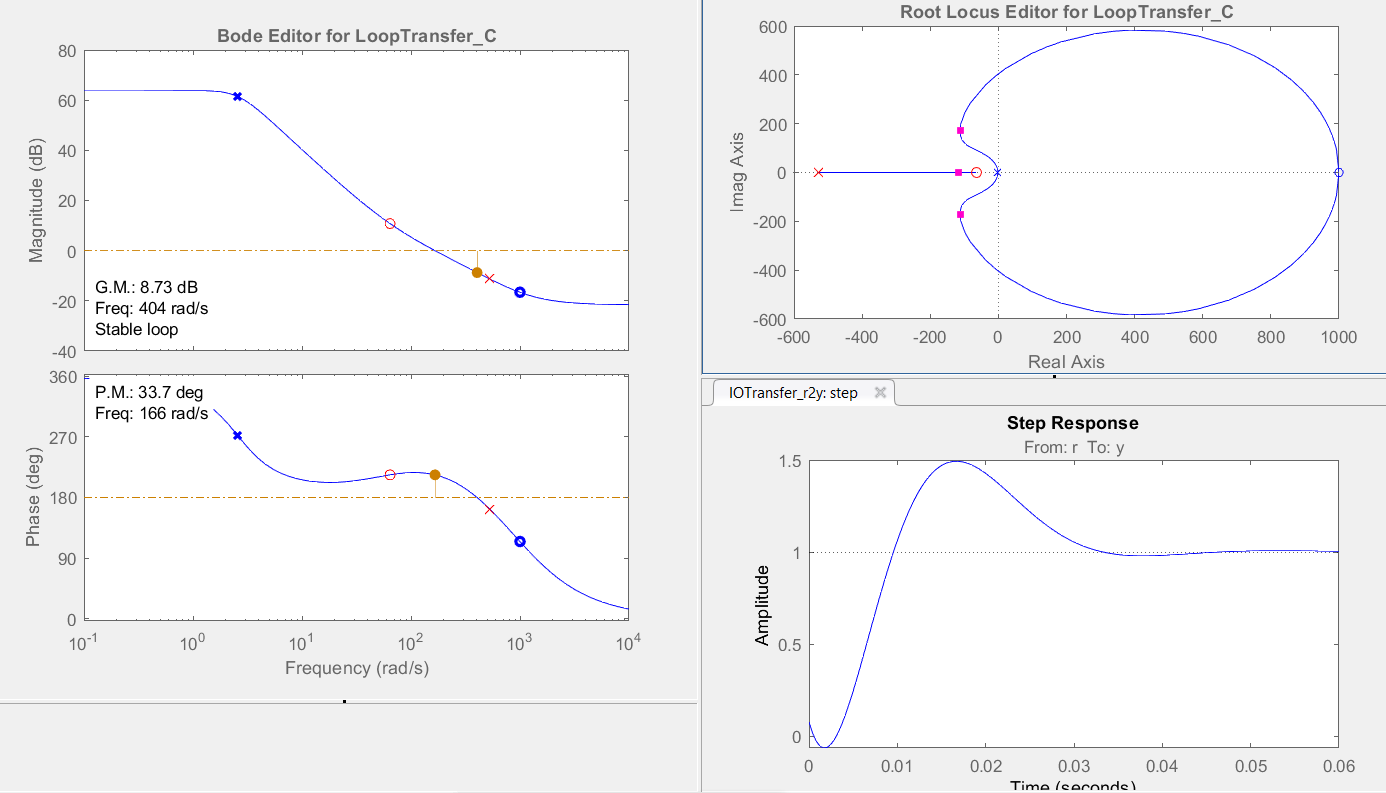

*Señal de control *

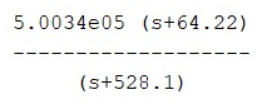

*Esquema de simulación*

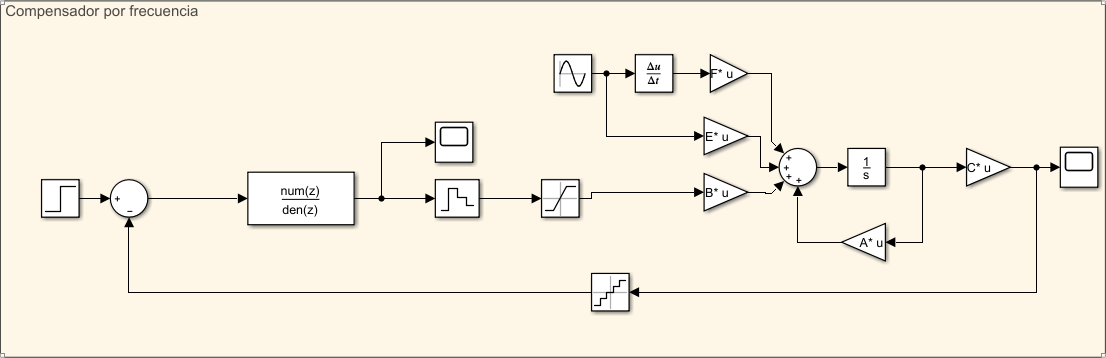

*Respuesta sin perturbación*

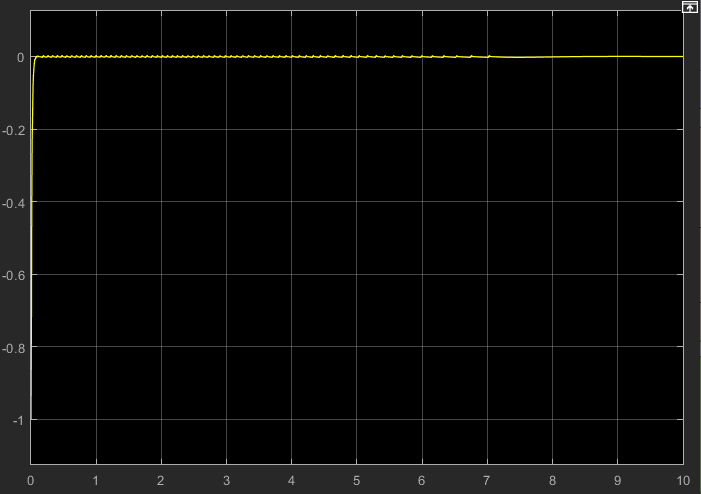

*Respuesta con perturbación*

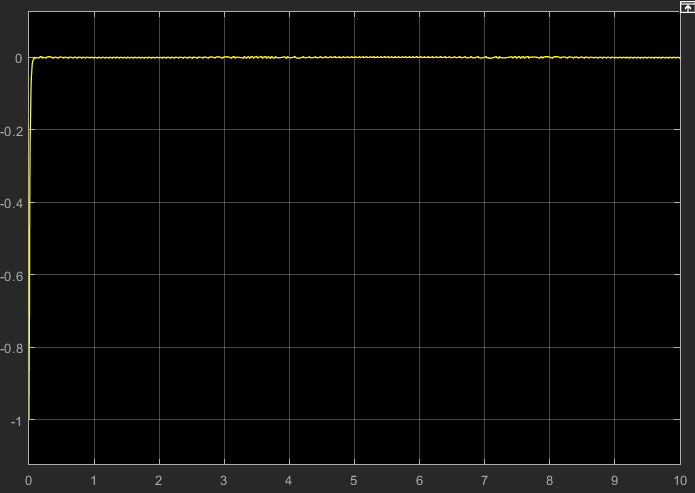

**Ecuacion en diferencia Frecuencia**


$$u(k)=\frac{5.3242*10^9*e(k)-4.6821*10^9*e(k-1)+4719*u(k-1)}{15281}$$


*SERVOSISTEMA*

% syms s
% 
% zd = 0.7;
% tsd = 0.08;
% Ts = tsd/10;
% 
% wn = 4/(zd*tsd);
%     
% T = 10;
% 
% num = [1/3];
% den = [1 10/3 20/3];
% [A, B, C, D] = tf2ss(num, den);
% Tf = tf(num, den);
% [AL,BL] = c2d(A, B, Ts);
% 
% Ss = -(zd*wn)+(1j*wn*sqrt(1-(zd^2)));
% PD = exp(Ts*Ss);
% 
% [m,n] = size(AL);
% 
% ce = zeros(n, 1);
% 
% cero = zeros(n, 2);
% ceros = zeros(1, n);
% cer = zeros(1, 2);
% cer(1, 2) = 1;
% cerr = zeros(1, 2);
% S = [BL AL*BL]
% det_S = det(S)
% 
% %Servosistema entrada escalón
% AE = [[AL; C*AL] [ce;1]]
% BE = [BL; C*BL]
% 
% [mE,nE] = size(AE);
% nE=3;
% convol = conv([1 -real(PD) -imag(PD)*1j], conv([1 -real(PD) imag(PD)*1j], [1 exp(-Ts*T*zd*wn)]))
% [t_c_f, t_c_c] = size(convol)
% for NBN = nE+2 : t_c_c
%    convol(nE+1) = convol(nE+1)+convol(NBN)
% end
% C_PDE = convol(1:nE+1)
% PDE = roots(C_PDE)
%     
% KKE = acker(AE, BE, PDE);
% e_ig = eig(AE-BE*KKE)
% Kiservo = KKE(end)
% KE = KKE(1:end-1)

*Esquema de simulación*

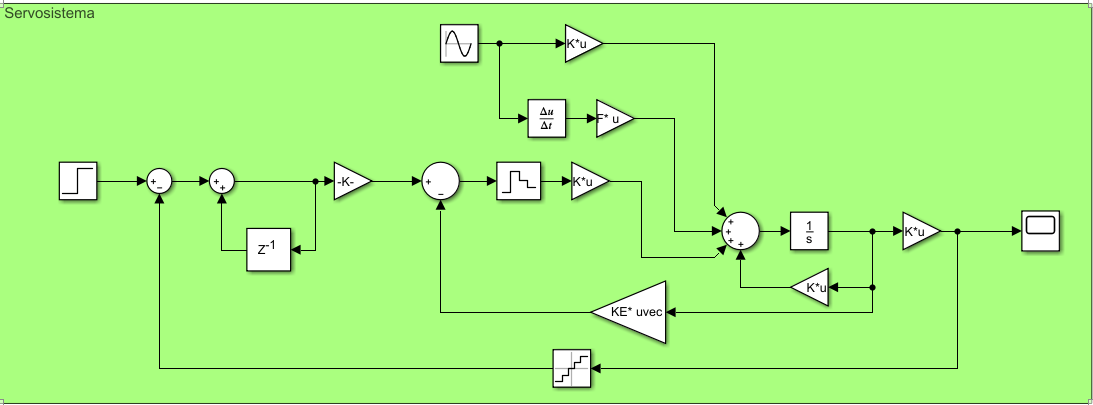

*Respuesta sin perturbación*

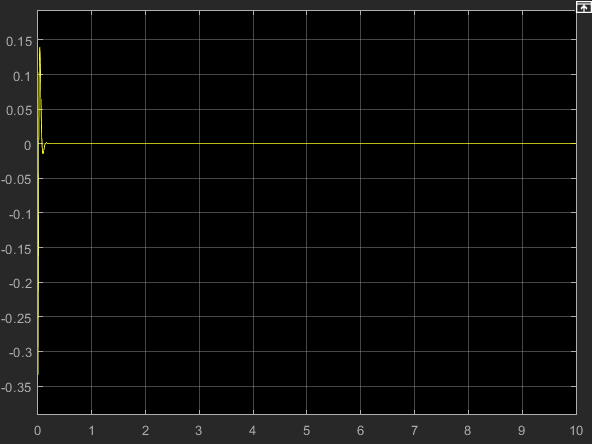

*Respuesta con perturbación*

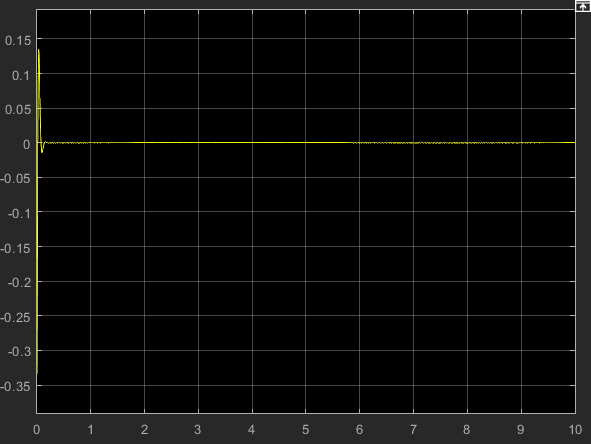

**Ecuación en diferencias Servosistema**


$$u(k)=-171*x(k)-9444.9*v(k)$$


**AN  ÁLISIS DE SISTEMAS**

El sistema con la mejor respuesta ante perturbaciones y en el menor tiempo sin ser propenso a oscilar en su respuesta fue el compensador por frecuencias. 

Los tiempos de muestreo en los compensadores se dividieron básicamente en 4 tipos, siendo tsd el tiempo de establecimiento, el cual varió en cada uno de los compensadores con el fin de mitigar en su mayoría los efectos provocados por las oscilaciones:

- Para PID continuo- discreto y compensador por frecuencias, el tiempo de muestro fue tsd/40

- Para PID discreto discreto, compensador LGR, servosistema, compensador por nulación de planta y tiempo mínimo de respuesta fue tsd/10.

- Para compensador por oscilaciones muertas se tomó tsd/2, ya que la planta era de orden 2